    root_folder = 'E:\Project_A\project_share\Project_A_image_cross';
    train_folder = 'train\left';
    class_folder_left = 'class\left';
    class_folder_right = 'class\right';
    class_folder_straight = 'class\straight';
    class_folder_U = 'class\U';
    
    full_path_train = fullfile(root_folder, train_folder);
    full_path_class_left = fullfile(root_folder, class_folder_left);
    full_path_class_right = fullfile(root_folder, class_folder_right);
    full_path_class_straight = fullfile(root_folder, class_folder_straight);
    full_path_class_U = fullfile(root_folder, class_folder_U);

    %% Load data
    imds = imageDatastore(full_path_train, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
    %% split train & validation
    [imdsTrain,imdsValidation] = splitEachLabel(imds,0.875);
    
    %% Load pretrain network
    net=googlenet;
    analyzeNetwork(net);
    inputSize = net.Layers(1).InputSize;
    

    imdsTest_left = imageDatastore(full_path_class_left, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    imdsTest_right = imageDatastore(full_path_class_right, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    imdsTest_straight = imageDatastore(full_path_class_straight, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    imdsTest_U = imageDatastore(full_path_class_U, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
    augimdsTest_left = augmentedImageDatastore(inputSize,imdsTest_left,"ColorPreprocessing","gray2rgb");
    augimdsTest_right = augmentedImageDatastore(inputSize,imdsTest_right,"ColorPreprocessing","gray2rgb");
    augimdsTest_straight = augmentedImageDatastore(inputSize,imdsTest_straight,"ColorPreprocessing","gray2rgb");
    augimdsTest_U = augmentedImageDatastore(inputSize,imdsTest_U,"ColorPreprocessing","gray2rgb");


    %% Replace final layer
    lgraph = layerGraph(net);
    [learnableLayer,classLayer] = findLayersToReplace(lgraph);
    [learnableLayer,classLayer] 

ans =   1×2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

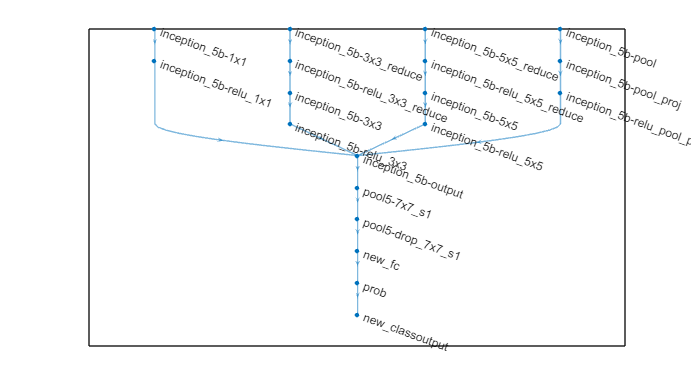

    numClasses = numel(categories(imdsTrain.Labels));
    if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
    elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    end

    lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

    newClassLayer = classificationLayer('Name','new_classoutput');
    lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

    figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
    plot(lgraph)
    ylim([0,10])

    %% Freeze Intial layers
%     layers = lgraph.Layers;
%     connections = lgraph.Connections;
% 
%     layers(1:10) = freezeWeights(layers(1:10));
%     lgraph = createLgraphUsingConnections(layers,connections);
%     

    %% Train
    pixelRange = [-30 30];
    scaleRange = [0.9 1.1];
    imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
    augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb');
    augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation,"ColorPreprocessing","gray2rgb");
    

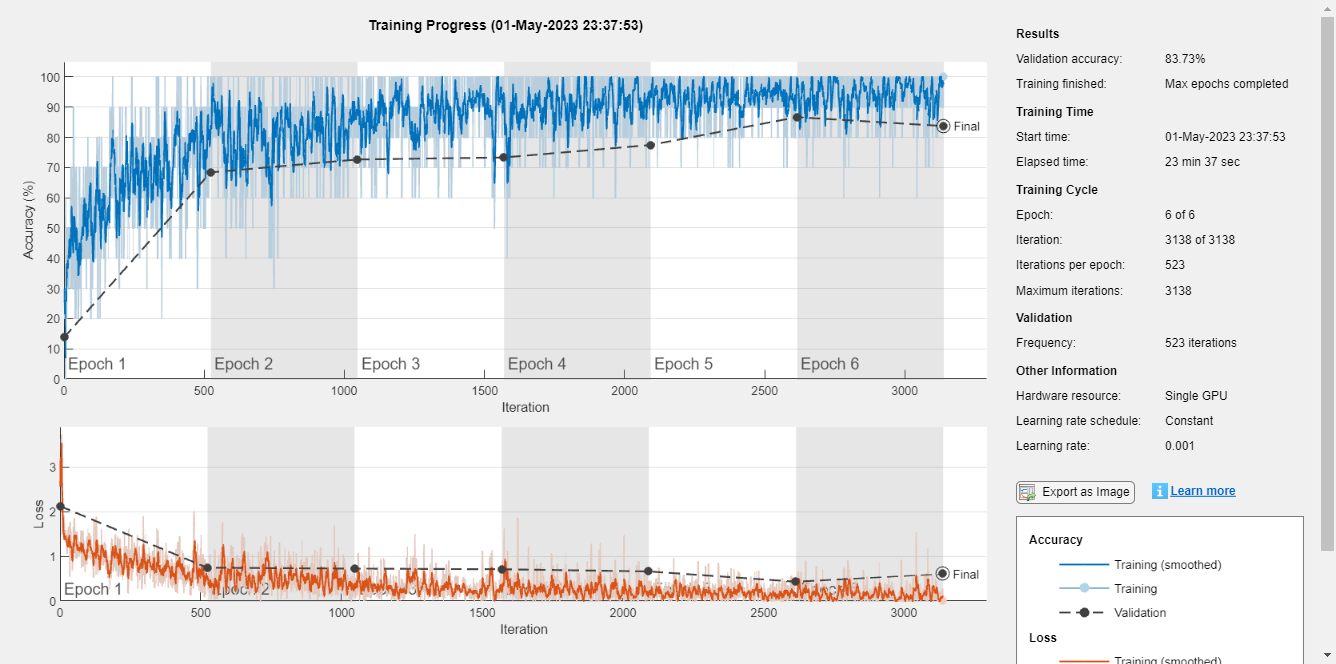

    miniBatchSize = 10;
    valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
    options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');
    options.ExecutionEnvironment = 'gpu';
    net = trainNetwork(augimdsTrain,lgraph,options);

    %% CLassify

    [YPred,probs] = classify(net,augimdsValidation);
    accuracy_train = mean(YPred == imdsValidation.Labels)

accuracy_train = 0.8373

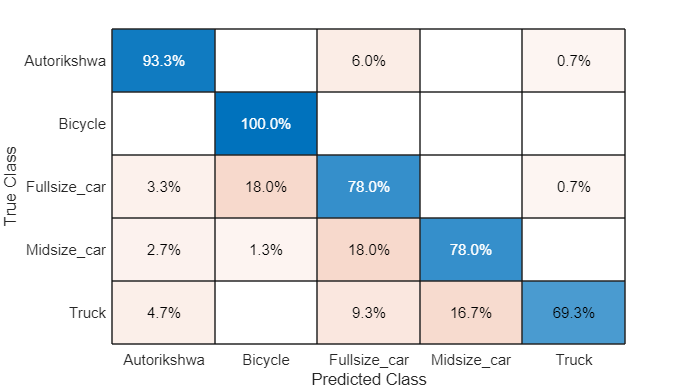

    confusionchart(imdsValidation.Labels,YPred,'Normalization','row-normalized')

    %% CLassify
    
    
    [YPred_left,probs_left] = classify(net,augimdsTest_left);
    [YPred_right,probs_right] = classify(net,augimdsTest_right);
    [YPred_straight,probs_straight] = classify(net,augimdsTest_straight);
    [YPred_U,probs_U] = classify(net,augimdsTest_U);
    accuracy_test_left = mean(YPred_left == imdsTest_left.Labels)

accuracy_test_left = 0.8529

    accuracy_test_right = mean(YPred_right == imdsTest_right.Labels)

accuracy_test_right = 0.8708

    accuracy_test_straight = mean(YPred_straight == imdsTest_straight.Labels)

accuracy_test_straight = 0.9440

    accuracy_test_U = mean(YPred_U == imdsTest_U.Labels)

accuracy_test_U = 0.8907

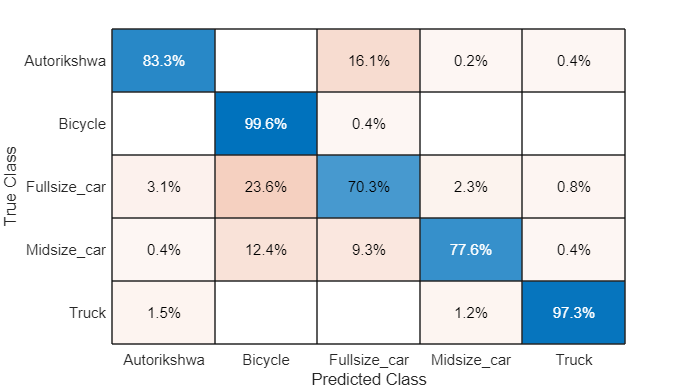

    confusionchart(imdsTest_left.Labels,YPred_left,'Normalization','row-normalized')

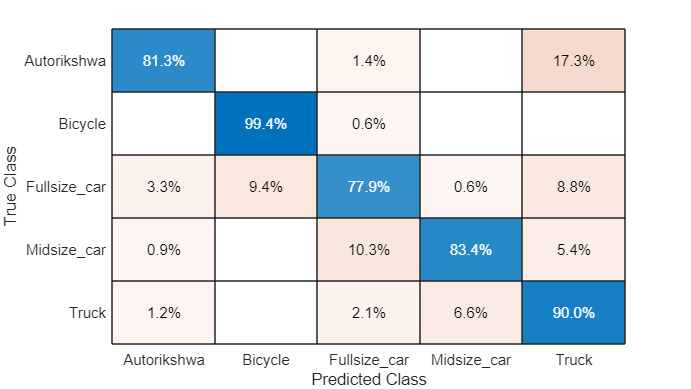

    confusionchart(imdsTest_right.Labels,YPred_right,'Normalization','row-normalized')

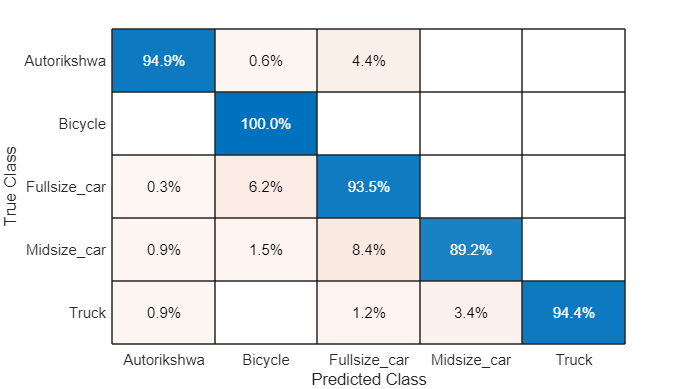

    confusionchart(imdsTest_straight.Labels,YPred_straight,'Normalization','row-normalized')

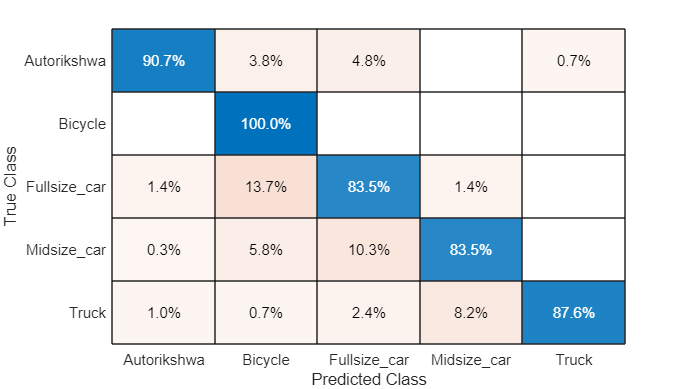

    confusionchart(imdsTest_U.Labels,YPred_U,'Normalization','row-normalized')

    F1_left  = calculateF1score(imdsTest_left.Labels,YPred_left)
    F1_right = calculateF1score(imdsTest_right.Labels,YPred_right)
    F1_straight = calculateF1score(imdsTest_straight.Labels,YPred_straight)
    F1_U = calculateF1score(imdsTest_U.Labels,YPred_U)
